# M-Scan to B-Scan Segmentation, Variant "Gapfinder" (Felix)

**Input**: An M-Scan called "D"

**Output**: An array containing the B-Scans that were segmented from the M-Scan

Challenges of this method:

- Increase the contrast of foreground / background

- Reduce noise

Enhance the contrast of an intensity image using histogram equalization.

This is because the image quality is actually quite bad, the difference between the grey values is too small to do segmentation on it.

Parameters:

disp(filename); % parameters set probably depend on individual scan

09052017034420__ascan_2.bin


medfilt2_iteration_Th = 1; % amount of times medfilt2 should be executed
im2bw_Th_1 = 0.53; % threshhold for first im2bw
gaussfilt_Th = 6; % amount of times to execute gaussian filter
im2bw_Th_2 = 0.47; % threshhold for second im2bw
scanlineTh = 88;  % the vertical position we look for the gaps
gap_min = 400; % minimal length a detected segment has to have to count as a gap
neighbourTh=850; % maximal distance between two points to count as neighbours, triggering the merge function on them

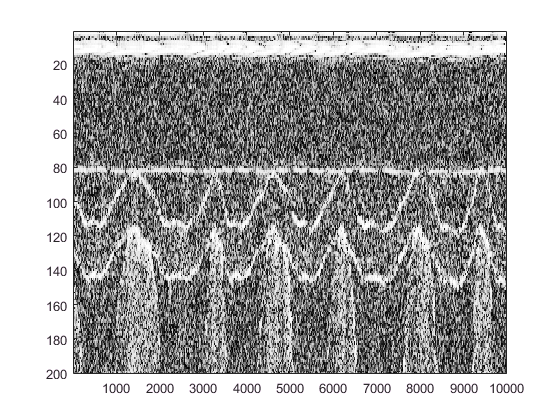

C = histeq(C); %possible alternative: imadjust(), gives worse results though
colormap gray;
imagesc(C);

Smooth it out

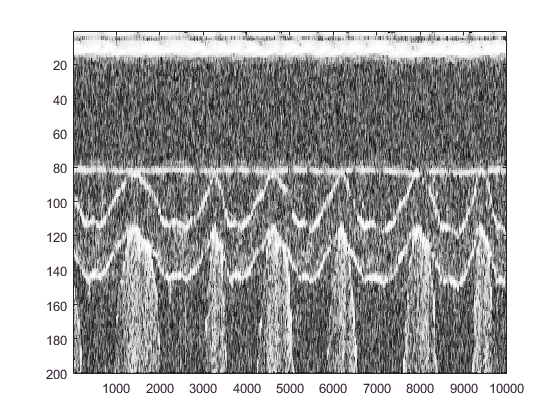

for i = 1:medfilt2_iteration_Th
    C = medfilt2(C,[3,3]);
end
imagesc(C)

Run Binaryze on it.

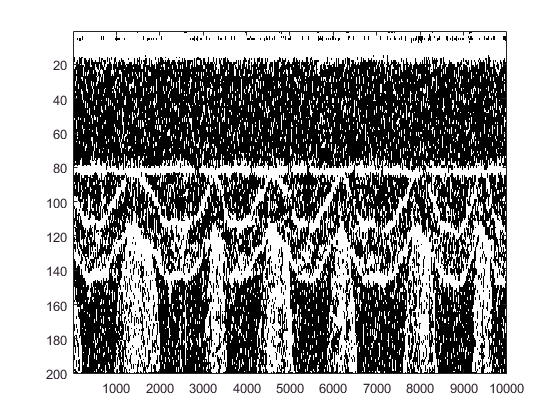

BW = im2bw(C, im2bw_Th_1);
imagesc(BW);

Try different filters for getting rid of noise.

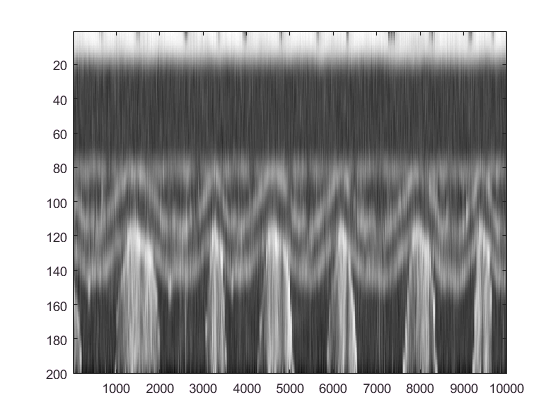

D_fixed=im2double(C);
Z = imgaussfilt(D_fixed, gaussfilt_Th);
imagesc(Z)

Run Binaryze on it (again).

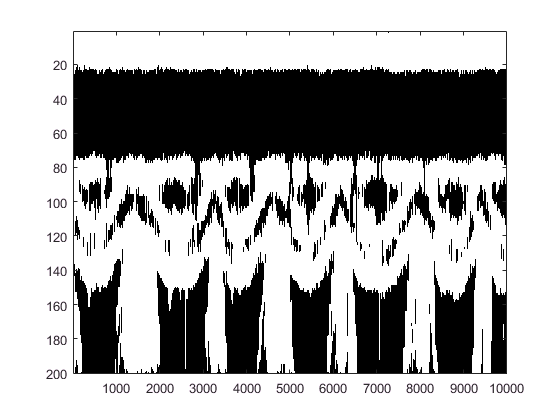

d_BW = im2bw(Z, im2bw_Th_2); % the higher the value the blacker the picture
figure; % attempt to make imagesc actually display something
colormap gray;
imagesc(d_BW);

Idea: Scan the picture at ca. scanlineTh (at about 80) to identify long gaps between white points (white areas). Then the topmost white color below it is probably a good point to seperate two b-scans.

First, find the gaps:

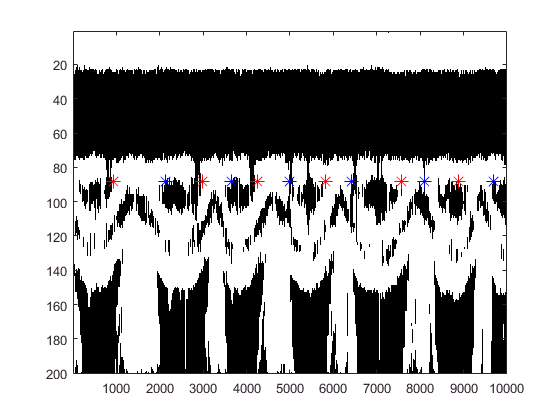

dDouble=im2double(d_BW);
imagesc(dDouble);
hold on;
scanline = dDouble(scanlineTh,:);
start=1;
i = 1;
while start < numel(scanline)
    % find a place where the gap begins (transition from black to white
    if scanline(start)==0 && scanline(start+1)==1
        % find the corresponding finish
        finish=start+1;
        while scanline(finish)~=0 && finish < length(scanline)
            finish=finish+1;
        end
        % only plot start and end if gap_min is met
        if finish-start > gap_min
            % plot the start
            plot(start,scanlineTh,'r*', 'MarkerSize',10);
            % plot the end
            plot(finish,scanlineTh,'b*', 'MarkerSize',10);
            results(i)=start;
            results(i+1)=finish;
            i = i +2;
%         else
%             disp("found start and finish but they are smaller than gap_min")
%             disp(finish-start)
%             disp(start)
%             disp(finish)
        end
        % set start to finish +1 to progress the search
        start= finish + 1;
    end
    start = start +1;
end
hold off;
hold on;

Find white points below the gap which should be the peak / segmentation point.

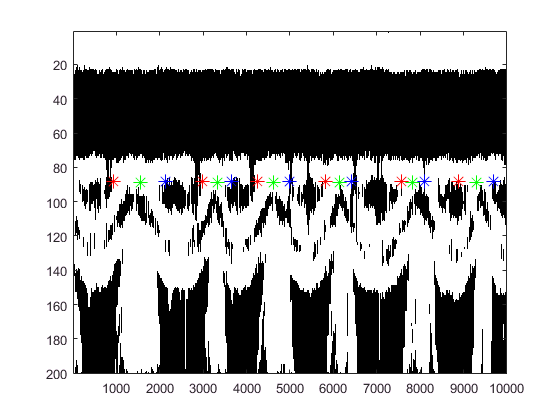

i = scanlineTh + 1;
l = 1;
k = 1;
resultsZ=[];
z=1;
amountResults=0;
while (amountResults<(numel(results)/2))
    % read current limits (finish and start)
    start=results(k);
    finish=results(k+1);
    yLine = scanlineTh+1; %horizontal start
%     disp(["switching section to:",num2str(start),num2str(finish)])
%     disp(["yLine: ",num2str(yLine)])
%     disp(["iteration / section:",num2str(k)])
%     disp(["numel(resultsZ)", num2str(numel(resultsZ))])
    % scan downwards within the limit of 50
    abort= 0; % initialize variable
    while (yLine < (scanlineTh + 50)) && abort ~= 1
        abort=0; %only abort if you find the result
        % scan through current line segment from start to finish
        % add white pixels to resultX
        resultsX = 0;
        l = 1;
        xPos=start;
        % disp(["going through yLine", num2str(yLine)]);
        while xPos < finish
            currentSegment=dDouble(i,[start,finish]);
            % only add the position if the image is white there
            if (dDouble(xPos) == 1)
                resultsX(l) = xPos;
                % disp(["adding xPos:", num2str(xPos)])
                l = l+1;
            end
            xPos= xPos+1;
        end
        % find median of resultsX if multiple white points occurred;
        if numel(resultsX) >= 1
            % disp(["content of results for line ",num2str(yLine)," is:",resultsX])
            resultsZ(z)=round(median(resultsX)); %round since median might be comma value, array needs integer
            % disp(["found result for current line, algo should switch segment", num2str(resultsZ(z))]);
            % disp(yLine);
            plot(resultsZ(z),yLine,'g*', 'MarkerSize',10);
            z= z+1;
            amountResults= amountResults+1;
            abort=1;
        end
        yLine = yLine+1;
    end
    k = k+2;
end
hold off;

Unify all points which are within a certain threshhold (neighbourTh)

i = 1;
resultsUnified = [];
rU = 1;
% first sort the array since we do a neighbourwise size comparison and we can otherwise skip neighbours
% if it is not sorted in the first place. this could be solved by doing an N:N comparison but this would
% increase the complexity of this algorithm
resultsP=sort(resultsZ);
while i < numel(resultsP)
    diff = (resultsP(i+1)-resultsP(i));
    disp(["calculating diff of ", i, resultsP(i), " and ", i+1, resultsP(i+1), ":", diff]);
    if diff < neighbourTh
        % find all following points which also seem too close
        loops = i + 1;
        while (loops+1 < numel(resultsP)) && ((resultsP(loops+1)-resultsP(i)) < neighbourTh)
           loops = loops + 1;
        end
        resultsUnified(rU) = round(median([resultsP(i:loops)]));
        disp([resultsP(i), " is too close to ", resultsP(i+1), " so we merge ",[resultsP(i:loops)]]);
        % skip the merged points
        i = loops + 1;
    else
        disp([resultsP(i), " is away far enough from ", resultsP(i+1), " so we are adding it"]);
        resultsUnified(rU) = resultsP(i);
        i = i + 1;
    end
    rU = rU+1;
end

    "calculating diff …"    "1"    "1546"    " and "    "2"    "3332"    ":"    "1786"



    "1546"    " is away far enough f…"    "3332"    " so we are adding it"



    "calculating diff …"    "2"    "3332"    " and "    "3"    "4611"    ":"    "1279"



    "3332"    " is away far enough f…"    "4611"    " so we are adding it"



    "calculating diff …"    "3"    "4611"    " and "    "4"    "6138"    ":"    "1527"



    "4611"    " is away far enough f…"    "6138"    " so we are adding it"



    "calculating diff …"    "4"    "6138"    " and "    "5"    "7814"    ":"    "1676"



    "6138"    " is away far enough f…"    "7814"    " so we are adding it"



    "calculating diff …"    "5"    "7814"    " and "    "6"    "9291"    ":"    "1477"



    "7814"    " is away far enough f…"    "9291"    " so we are adding it"



% add the last one if previous operation hasnt been a merge, e.g. it is not too close to its previous neighbour
if (i <= numel(resultsP))
    resultsUnified(rU) = resultsP(i);
end

Display the current points

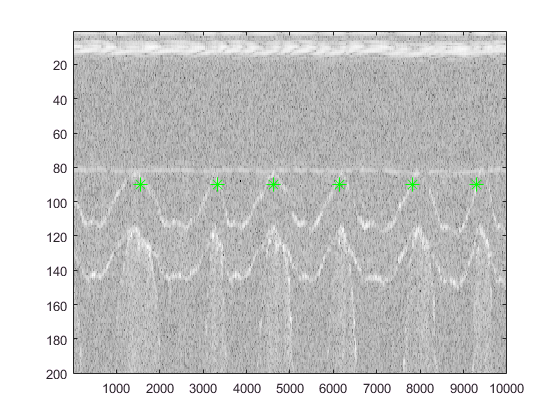

figure;
colormap gray;
imagesc(original);
hold on;
i = 1;
while i <= numel(resultsUnified)
    plot(resultsUnified(i),yLine,'g*', 'MarkerSize',10);
    i = i + 1;
end
hold off;